clc
clear all


k1=0.8

k1 = 0.8000

b2=0.8

b2 = 0.8000

k2=0.28

k2 = 0.2800

b1=0.28

b1 = 0.2800

m1=1

m1 = 1

m2=1

m2 = 1

syms s

X2_to_X1 =(b1*s+k1)/(m2*s^2  + (b2+b1)*s +(k2+k1))

$$X2\_to\_X1 = \frac{\frac{7\,s}{25}+\frac{4}{5}}{s^{2}+\frac{27\,s}{25}+\frac{27}{25}}$$


X1_to_U = (m2*s^2  + (b2+b1)*s +(k2+k1))/((m2*s^2  + (b2+b1)*s +(k2+k1))*(m1*s^2+b1*s+k1)-(b1*s+k1)^2)

$$X1\_to\_U = \frac{s^{2}+\frac{27\,s}{25}+\frac{27}{25}}{\left(s^{2}+\frac{7\,s}{25}+\frac{4}{5}\right)\,\left(s^{2}+\frac{27\,s}{25}+\frac{27}{25}\right)-{\left(\frac{7\,s}{25}+\frac{4}{5}\right)}^{2}}$$


X2_to_U = X2_to_X1 * X1_to_U

$$X2\_to\_U = \frac{\frac{7\,s}{25}+\frac{4}{5}}{\left(s^{2}+\frac{7\,s}{25}+\frac{4}{5}\right)\,\left(s^{2}+\frac{27\,s}{25}+\frac{27}{25}\right)-{\left(\frac{7\,s}{25}+\frac{4}{5}\right)}^{2}}$$

% Simplify X2_to_U
X2_to_U_simplified = simplify(X2_to_U);
display(X2_to_U_simplified)

$$X2\_to\_U\_simplified = \frac{175\,s+500}{625\,s^{4}+850\,s^{3}+1315\,s^{2}+449\,s+140}$$

# Q3

% Obtain numerator and denominator of X2_to_U_simplified
[numerator, denominator] = numden(X2_to_U_simplified);

% Display numerator and denominator
disp('Numerator of X2_to_U_simplified:');

Numerator of X2_to_U_simplified:


disp(numerator);

$$175\,s+500$$

disp('Denominator of X2_to_U_simplified:');

Denominator of X2_to_U_simplified:


disp(denominator);

$$625\,s^{4}+850\,s^{3}+1315\,s^{2}+449\,s+140$$


% Convert symbolic coefficients to numeric values
coefficients_numerator = fliplr(double(coeffs(numerator, s)));
coefficients_denominator = fliplr(double(coeffs(denominator, s)));

% Display numeric coefficients
disp('Numeric coefficients of numerator:');

Numeric coefficients of numerator:


disp(fliplr(coefficients_numerator));

   500   175



disp('Numeric coefficients of denominator:');

Numeric coefficients of denominator:


disp(fliplr(coefficients_denominator));

         140         449        1315         850         625




% Create transfer function
g = tf((coefficients_numerator), (coefficients_denominator));
display(g);

g =
 
                 175 s + 500
  ------------------------------------------
  625 s^4 + 850 s^3 + 1315 s^2 + 449 s + 140
 
Continuous-time transfer function.




% Display step response information
stepinfo(g);
display(stepinfo(g))

  struct with fields:

        RiseTime: 3.8222
    SettlingTime: 22.3115
     SettlingMin: 3.3010
     SettlingMax: 4.2589
       Overshoot: 19.2502
      Undershoot: 0
            Peak: 4.2589
        PeakTime: 9.6965



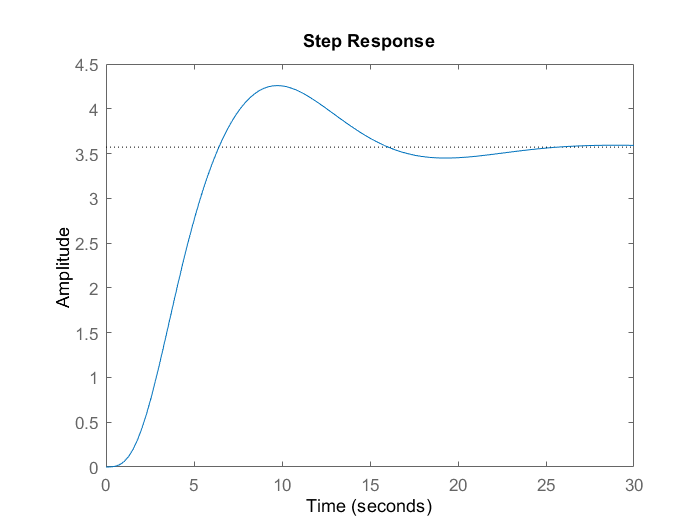

step(g)

sys_info = stepinfo(g);
rise_time = sys_info.RiseTime;   
T_s = rise_time/10;  
display(T_s)

T_s = 0.3822

z = tf('z',T_s);
G_z = c2d(g,T_s,'tustin')

G_z =
 
                                                                    
  0.002251 z^4 + 0.006093 z^3 + 0.004771 z^2 + 0.0002681 z          
                                                                    
                                                         - 0.0006611
                                                                    
  ------------------------------------------------------------------
                                                         
             z^4 - 3.359 z^3 + 4.358 z^2 - 2.6 z + 0.6052
                                                         
 
Sample time: 0.38222 seconds
Discrete-time transfer function.



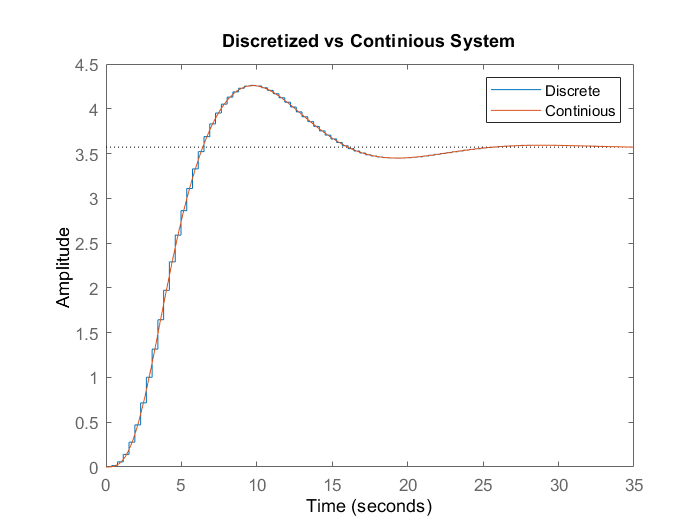

[numerator, denominator] = tfdata(G_z, 'v');
figure()
hold on
step(G_z)
step(g)
title('Discretized vs Continious System')
legend('Discrete','Continious')
hold off

# T

% Define the number of sinusoidal components
num_components = 6;
G_i = randi([1, 7], 1, 6);% Random amplitudes between 0 and 7
display(G_i)

G_i =      6     6     4     5     7     4


omega_i = randi([1, 7], 1, 6); % Random angular frequencies between 0 and 7
display(omega_i)

omega_i =      1     7     5     3     7     2



% Create a time vector for simulation
t = 0:T_s:50; % Adjust the time vector as needed

% Initialize the input signal
u = ones(size(t));

% Generate the sum of sinusoidal inputs
for i = 1:num_components
    u = u + G_i(i) * sin(omega_i(i) * t);
end
disp(u)

  Columns 1 through 7

    1.0000   20.1761   -0.0548   18.7156   -6.1622   10.4311   -3.6201

  Columns 8 through 14

    6.7416   10.9095  -17.7016   10.6969   -9.2095    5.7336   -7.2019

  Columns 15 through 21

   -8.4585   -3.7575  -18.6957   23.4224    2.4202   13.7730    5.1125

  Columns 22 through 28

   -0.8017    8.8376   -7.1545   20.5615  -13.3855   -0.0716    2.1398

  Columns 29 through 35

   -5.8051    6.1038  -16.8155    3.0178  -20.9285    7.4564   16.4804

  Columns 36 through 42

    2.0348   17.3615   -7.0318   12.1463   -6.4705   11.3460    5.5612

  Columns 43 through 49

  -15.3658   10.8675  -10.5212    7.8764  -10.9637   -4.9535   -7.7728

  Columns 50 through 56

  -14.4742   24.5062    0.0992   16.4948    1.1088    2.5626    5.6627

  Columns 57 through 63

   -4.3463   19.8066  -16.6069    4.1942   -1.5572   -2.5843    3.0446

  Columns 64 through 70

  -15.6817    2.6993  -22.3729   13.4017   12.2850    4.9728   14.8701

  Columns 71 through 77

   -6.65

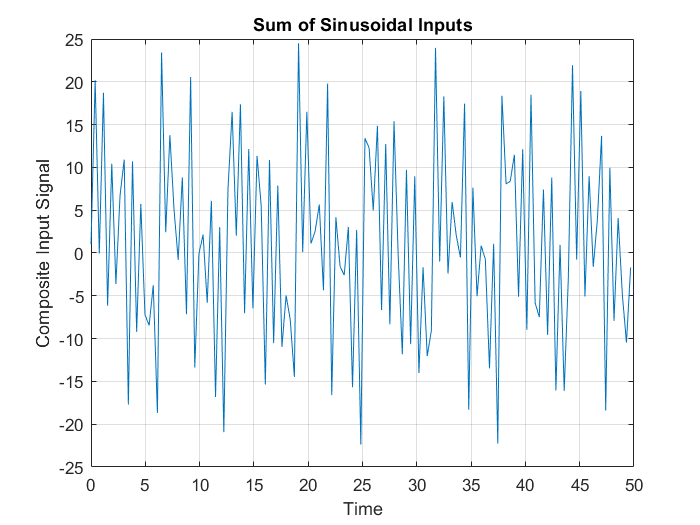



figure;
plot(t, u);
xlabel('Time');
ylabel('Composite Input Signal');
title('Sum of Sinusoidal Inputs');
grid on;

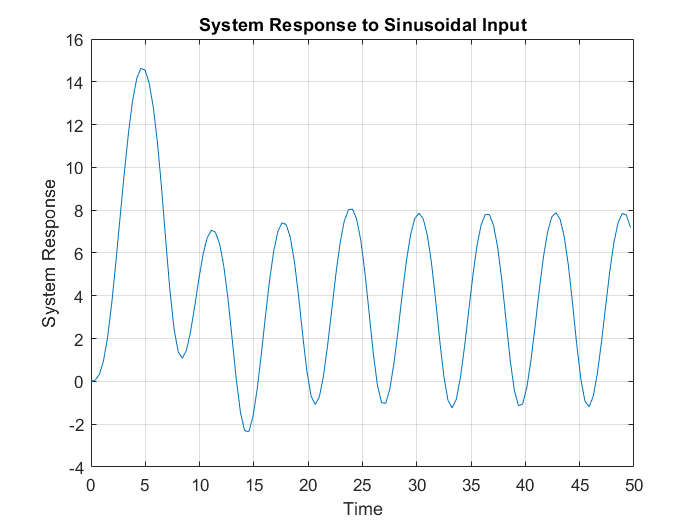




figure()
[y,t_out] = lsim(G_z,u,t);
% Plot the system response
figure;
plot(t_out, y);
xlabel('Time');
ylabel('System Response');
title('System Response to Sinusoidal Input');
grid on;

# Se

[parameter,regres_matrix] = least_square(y,u,t);

Regression Matrix:
  Columns 1 through 7

         0         0         0         0    1.0000         0         0
   -0.0023         0         0         0   20.1761    1.0000         0
   -0.0591   -0.0023         0         0   -0.0548   20.1761    1.0000
   -0.3162   -0.0591   -0.0023         0   18.7156   -0.0548   20.1761
   -0.9491   -0.3162   -0.0591   -0.0023   -6.1622   18.7156   -0.0548
   -2.0674   -0.9491   -0.3162   -0.0591   10.4311   -6.1622   18.7156
   -3.6577   -2.0674   -0.9491   -0.3162   -3.6201   10.4311   -6.1622
   -5.5861   -3.6577   -2.0674   -0.9491    6.7416   -3.6201   10.4311
   -7.6570   -5.5861   -3.6577   -2.0674   10.9095    6.7416   -3.6201
   -9.6946   -7.6570   -5.5861   -3.6577  -17.7016   10.9095    6.7416
  -11.5622   -9.6946   -7.6570   -5.5861   10.6969  -17.7016   10.9095
  -13.0963  -11.5622   -9.6946   -7.6570   -9.2095   10.6969  -17.7016
  -14.1410  -13.0963  -11.5622   -9.6946    5.7336   -9.2095   10.6969
  -14.6257  -14.1410  -13.0963  -11

display(parameter)

parameter =    -3.3594
    4.3576
   -2.5997
    0.6052
    0.0023
    0.0061
    0.0048
    0.0003
   -0.0007


y_estimated = regres_matrix*parameter;
0.5*sum((y-y_estimated).^2)

ans = 2.4048e-18



% % Extract numerator and denominator coefficients
% numerator_coeffs = parameter(5:9)';
% denominator_coeffs = [1,parameter(1:4)'];
% 
% % Create transfer function G_seZ in discrete time
% G_seZ = tf(numerator_coeffs,denominator_coeffs, T_s);
% G_se = d2c(G_seZ)
% display(G_se)

# je

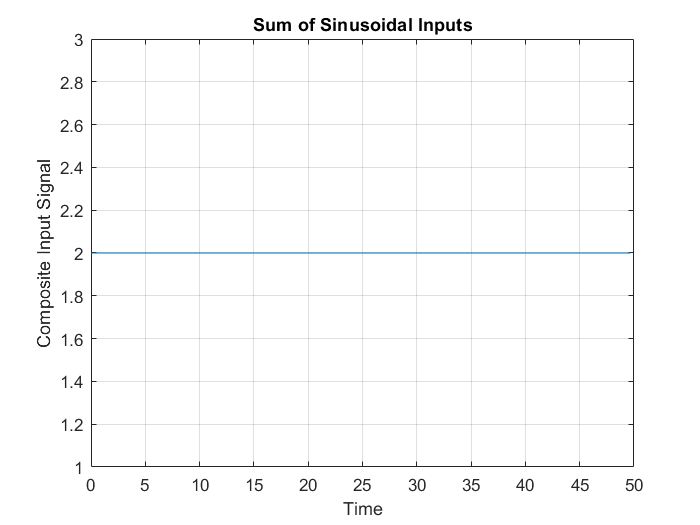

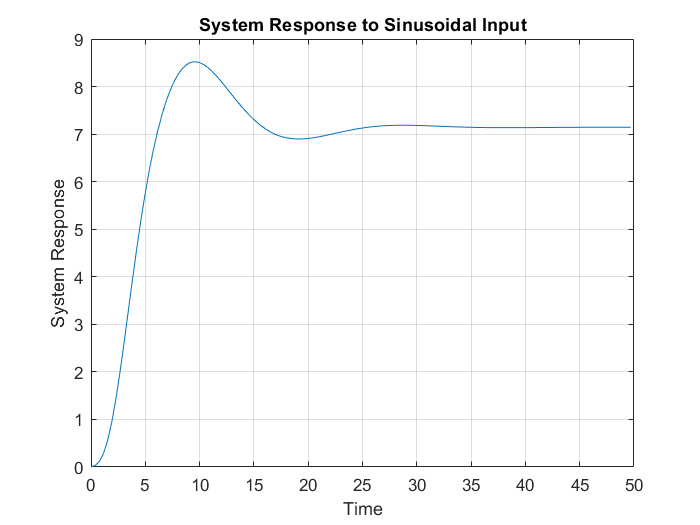

Regression Matrix:
  Columns 1 through 7

         0         0         0         0    2.0000         0         0
   -0.0045         0         0         0    2.0000    2.0000         0
   -0.0318   -0.0045         0         0    2.0000    2.0000    2.0000
   -0.1135   -0.0318   -0.0045         0    2.0000    2.0000    2.0000
   -0.2811   -0.1135   -0.0318   -0.0045    2.0000    2.0000    2.0000
   -0.5552   -0.2811   -0.1135   -0.0318    2.0000    2.0000    2.0000
   -0.9416   -0.5552   -0.2811   -0.1135    2.0000    2.0000    2.0000
   -1.4313   -0.9416   -0.5552   -0.2811    2.0000    2.0000    2.0000
   -2.0043   -1.4313   -0.9416   -0.5552    2.0000    2.0000    2.0000
   -2.6334   -2.0043   -1.4313   -0.9416    2.0000    2.0000    2.0000
   -3.2897   -2.6334   -2.0043   -1.4313    2.0000    2.0000    2.0000
   -3.9463   -3.2897   -2.6334   -2.0043    2.0000    2.0000    2.0000
   -4.5810   -3.9463   -3.2897   -2.6334    2.0000    2.0000    2.0000
   -5.1773   -4.5810   -3.9463   -3

parameter =    -3.3594
    4.3576
   -2.5997
    0.6052
    0.0023
    0.0061
    0.0048
    0.0003
   -0.0007


loss


   4.5849e-13



for j = 1:1
    
    % Create a time vector for simulation
    t = 0:T_s:50; % Adjust the time vector as needed
    % Initialize the input signal
    u = ones(size(t))*2;
    % Generate the sum of sinusoidal input
    figure;
    plot(t, u);
    xlabel('Time');
    ylabel('Composite Input Signal');
    title('Sum of Sinusoidal Inputs');
    grid on;

    figure()
    [y,t_out] = lsim(G_z,u,t);
    % Plot the system response
    figure;
    plot(t_out, y);
    xlabel('Time');
    ylabel('System Response');
    title('System Response to Sinusoidal Input');
    grid on;
    [parameter,regres_matrix] = least_square(y,u,t);
    display(parameter)
    y_estimated = regres_matrix*parameter;
    disp("loss")
    disp(0.5*sum((y-y_estimated).^2))
    
end

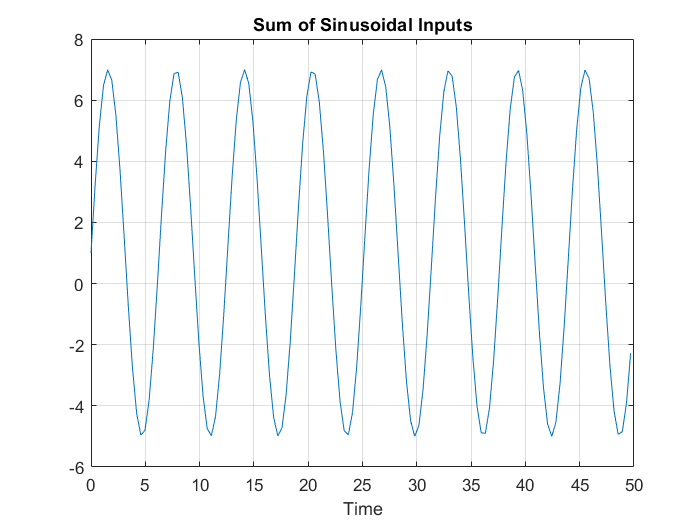

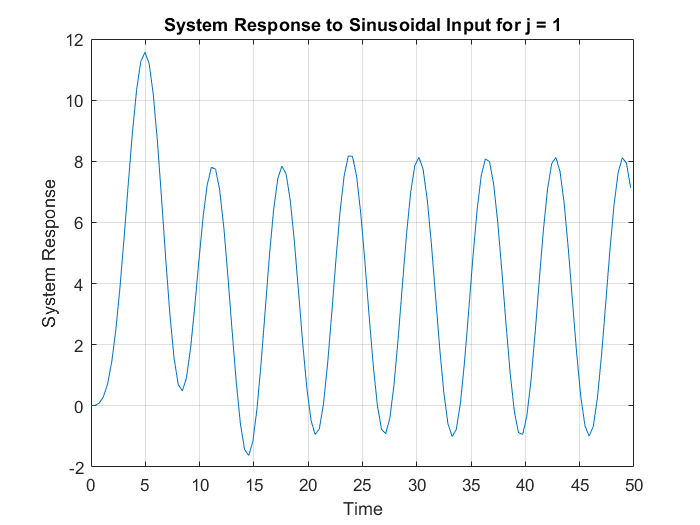

Regression Matrix:
  Columns 1 through 7

         0         0         0         0    1.0000         0         0
   -0.0023         0         0         0    3.2379    1.0000         0
   -0.0209   -0.0023         0         0    5.1528    3.2379    1.0000
   -0.0967   -0.0209   -0.0023         0    6.4683    5.1528    3.2379
   -0.3010   -0.0967   -0.0209   -0.0023    6.9947    6.4683    5.1528
   -0.7229   -0.3010   -0.0967   -0.0209    6.6560    6.9947    6.4683
   -1.4435   -0.7229   -0.3010   -0.0967    5.5009    6.6560    6.9947
   -2.5076   -1.4435   -0.7229   -0.3010    3.6964    5.5009    6.6560
   -3.9028   -2.5076   -1.4435   -0.7229    1.5026    3.6964    5.5009
   -5.5484   -3.9028   -2.5076   -1.4435   -0.7636    1.5026    3.6964
   -7.3009   -5.5484   -3.9028   -2.5076   -2.7754   -0.7636    1.5026
   -8.9717   -7.3009   -5.5484   -3.9028   -4.2423   -2.7754   -0.7636
  -10.3561   -8.9717   -7.3009   -5.5484   -4.9526   -4.2423   -2.7754
  -11.2675  -10.3561   -8.9717   -7

     2



parameter =    -3.3594
    4.3576
   -2.5997
    0.6052
    0.0023
    0.0061
    0.0048
    0.0003
   -0.0007


loss


   1.2896e-16



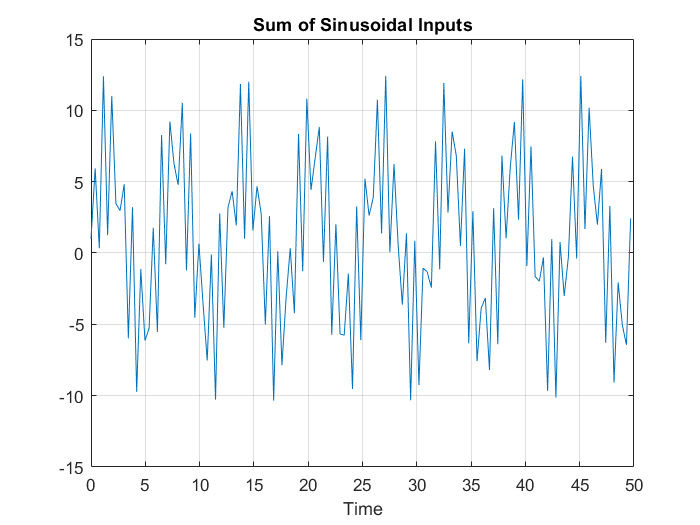

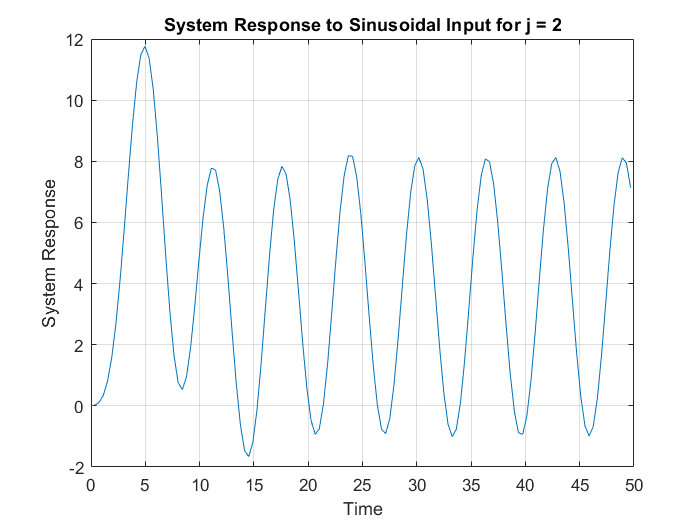

Regression Matrix:
  Columns 1 through 7

         0         0         0         0    1.0000         0         0
   -0.0023         0         0         0    5.9342    1.0000         0
   -0.0270   -0.0023         0         0    0.3353    5.9342    1.0000
   -0.1226   -0.0270   -0.0023         0   12.3792    0.3353    5.9342
   -0.3586   -0.1226   -0.0270   -0.0023    1.2514   12.3792    0.3353
   -0.8199   -0.3586   -0.1226   -0.0270   11.0065    1.2514   12.3792
   -1.5821   -0.8199   -0.3586   -0.1226    3.4713   11.0065    1.2514
   -2.6839   -1.5821   -0.8199   -0.3586    2.9721    3.4713   11.0065
   -4.1096   -2.6839   -1.5821   -0.8199    4.8262    2.9721    3.4713
   -5.7751   -4.1096   -2.6839   -1.5821   -5.9776    4.8262    2.9721
   -7.5373   -5.7751   -4.1096   -2.6839    3.2167   -5.9776    4.8262
   -9.2076   -7.5373   -5.7751   -4.1096   -9.7341    3.2167   -5.9776
  -10.5835   -9.2076   -7.5373   -5.7751   -1.1326   -9.7341    3.2167
  -11.4809  -10.5835   -9.2076   -7

     3



parameter =    -3.3594
    4.3576
   -2.5997
    0.6052
    0.0023
    0.0061
    0.0048
    0.0003
   -0.0007


loss


   6.8396e-16



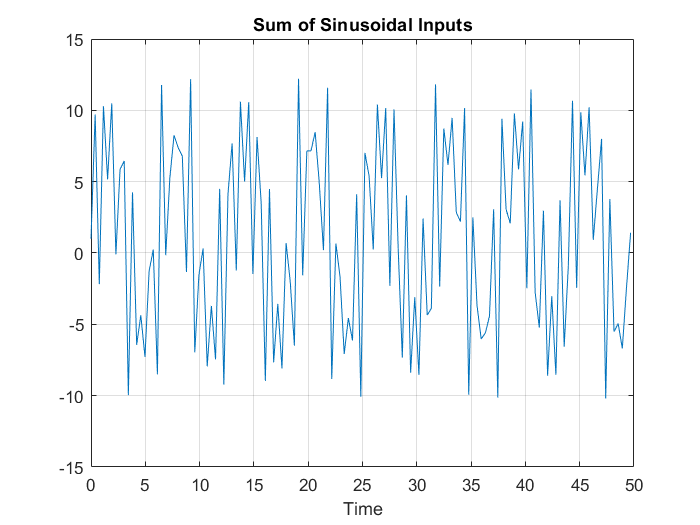

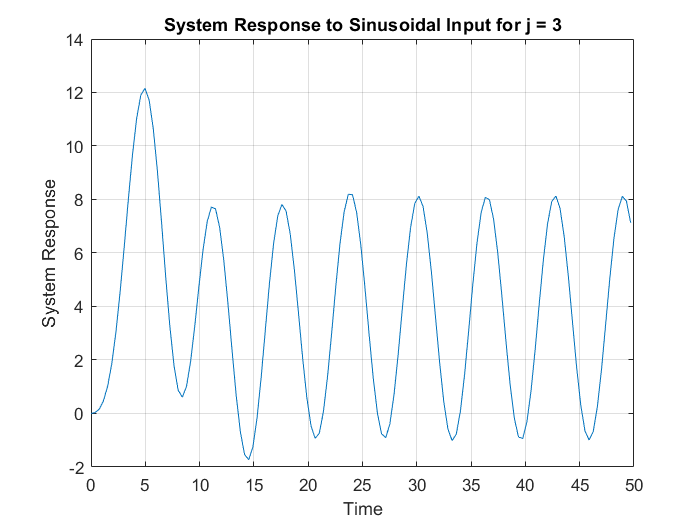

Regression Matrix:
  Columns 1 through 7

         0         0         0         0    1.0000         0         0
   -0.0023         0         0         0    9.7049    1.0000         0
   -0.0355   -0.0023         0         0   -2.1817    9.7049    1.0000
   -0.1685   -0.0355   -0.0023         0   10.2886   -2.1817    9.7049
   -0.4735   -0.1685   -0.0355   -0.0023    5.1638   10.2886   -2.1817
   -1.0134   -0.4735   -0.1685   -0.0355   10.4856    5.1638   10.2886
   -1.8548   -1.0134   -0.4735   -0.1685   -0.0934   10.4856    5.1638
   -3.0368   -1.8548   -1.0134   -0.4735    5.8725   -0.0934   10.4856
   -4.5246   -3.0368   -1.8548   -1.0134    6.4549    5.8725   -0.0934
   -6.2254   -4.5246   -3.0368   -1.8548   -9.9651    6.4549    5.8725
   -8.0078   -6.2254   -4.5246   -3.0368    4.2497   -9.9651    6.4549
   -9.6807   -8.0078   -6.2254   -4.5246   -6.4361    4.2497   -9.9651
  -11.0352   -9.6807   -8.0078   -6.2254   -4.3670   -6.4361    4.2497
  -11.9028  -11.0352   -9.6807   -8

     4



parameter =    -3.3594
    4.3576
   -2.5997
    0.6052
    0.0023
    0.0061
    0.0048
    0.0003
   -0.0007


loss


   1.1650e-17



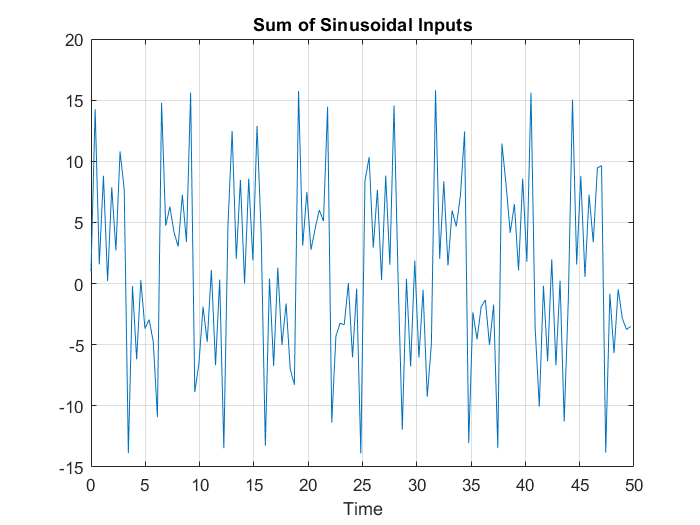

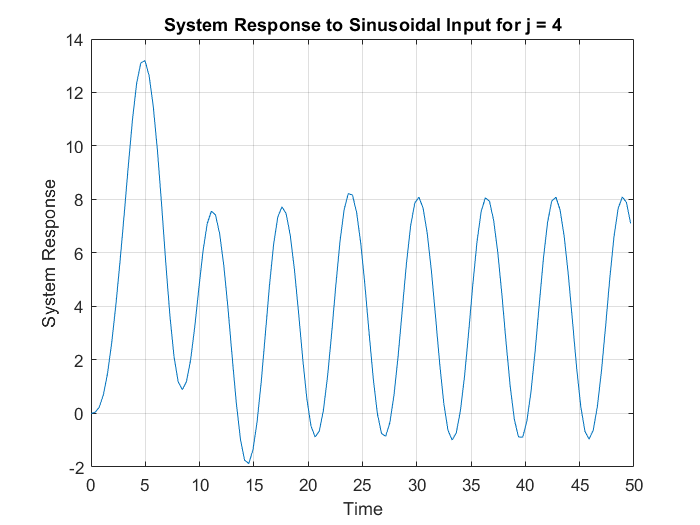

Regression Matrix:
  Columns 1 through 7

         0         0         0         0    1.0000         0         0
   -0.0023         0         0         0   14.2618    1.0000         0
   -0.0458   -0.0023         0         0    1.5691   14.2618    1.0000
   -0.2391   -0.0458   -0.0023         0    8.8190    1.5691   14.2618
   -0.7075   -0.2391   -0.0458   -0.0023    0.2033    8.8190    1.5691
   -1.5172   -0.7075   -0.2391   -0.0458    7.8723    0.2033    8.8190
   -2.6601   -1.5172   -0.7075   -0.2391    2.7162    7.8723    0.2033
   -4.0761   -2.6601   -1.5172   -0.7075   10.7982    2.7162    7.8723
   -5.6906   -4.0761   -2.6601   -1.5172    7.6997   10.7982    2.7162
   -7.4512   -5.6906   -4.0761   -2.6601  -13.8663    7.6997   10.7982
   -9.2841   -7.4512   -5.6906   -4.0761   -0.2062  -13.8663    7.6997
  -11.0009   -9.2841   -7.4512   -5.6906   -6.2025   -0.2062  -13.8663
  -12.3416  -11.0009   -9.2841   -7.4512    0.2811   -6.2025   -0.2062
  -13.1040  -12.3416  -11.0009   -9

     5



parameter =    -3.3594
    4.3576
   -2.5997
    0.6052
    0.0023
    0.0061
    0.0048
    0.0003
   -0.0007


loss


   1.1853e-17



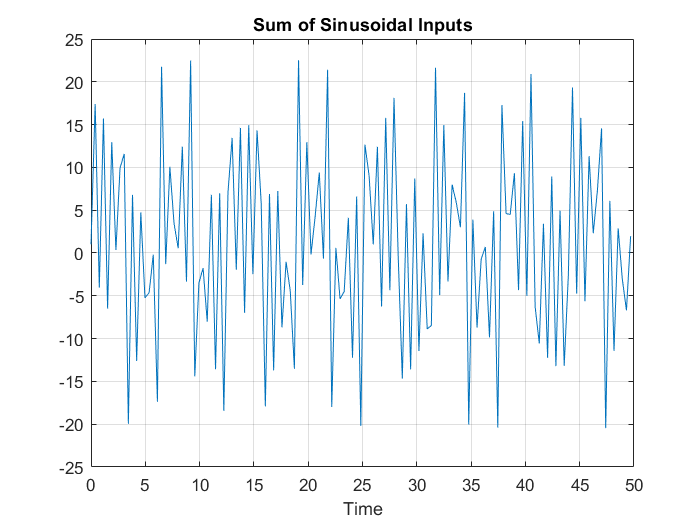

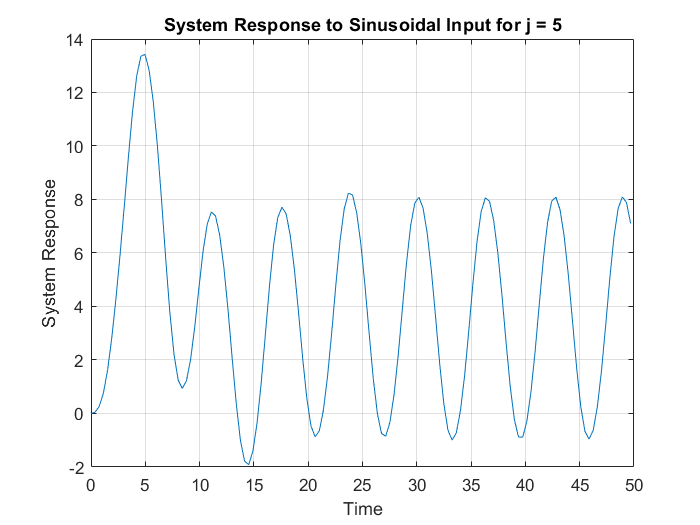

Regression Matrix:
  Columns 1 through 7

         0         0         0         0    1.0000         0         0
   -0.0023         0         0         0   17.4075    1.0000         0
   -0.0528   -0.0023         0         0   -4.0513   17.4075    1.0000
   -0.2694   -0.0528   -0.0023         0   15.7150   -4.0513   17.4075
   -0.7747   -0.2694   -0.0528   -0.0023   -6.4973   15.7150   -4.0513
   -1.6304   -0.7747   -0.2694   -0.0528   12.9480   -6.4973   15.7150
   -2.8218   -1.6304   -0.7747   -0.2694    0.3482   12.9480   -6.4973
   -4.2817   -2.8218   -1.6304   -0.7747    9.9533    0.3482   12.9480
   -5.9319   -4.2817   -2.8218   -1.6304   11.5773    9.9533    0.3482
   -7.7156   -5.9319   -4.2817   -2.8218  -19.9493   11.5773    9.9533
   -9.5598   -7.7156   -5.9319   -4.2817    6.7845  -19.9493   11.5773
  -11.2761   -9.5598   -7.7156   -5.9319  -12.6096    6.7845  -19.9493
  -12.6069  -11.2761   -9.5598   -7.7156    4.7378  -12.6096    6.7845
  -13.3529  -12.6069  -11.2761   -9

     6



parameter =    -3.3594
    4.3576
   -2.5997
    0.6052
    0.0023
    0.0061
    0.0048
    0.0003
   -0.0007


loss


   1.7097e-18





for j = 1:5
    
    % Create a time vector for simulation
    t = 0:T_s:50; % Adjust the time vector as needed

    % Initialize the input signal
    u = ones(size(t));

    % Generate the sum of sinusoidal inputs
    for i = 1:j
         u = u + G_i(i) * sin(omega_i(i) * t);
    end
    
    figure;
    plot(t, u);
    xlabel('Time');
    title(['Sum of Sinusoidal Inputs for j = ', num2str(j)]);
    title('Sum of Sinusoidal Inputs');
    grid on;

    figure()
    [y,t_out] = lsim(G_z,u,t);
    % Plot the system response
    figure;
    plot(t_out, y);
    xlabel('Time');
    ylabel('System Response');
    title(['System Response to Sinusoidal Input for j = ', num2str(j)]);
    grid on;

    [parameter,regres_matrix] = least_square(y,u,t);
    disp(j+1)
    display(parameter)
    y_estimated = regres_matrix*parameter;
    disp("loss")
    disp(0.5*sum((y-y_estimated).^2))

end

# #che

% Create a time vector for simulation
t = 0:T_s:50; % Adjust the time vector as needed

% Initialize the input signal
u = ones(size(t));

% Generate the sum of sinusoidal inputs
for i = 1:num_components
    u = u + G_i(i) * sin(omega_i(i) * t);
end



figure;
plot(t, u);
xlabel('Time');
ylabel('Composite Input Signal');
title('Sum of Sinusoidal Inputs');
grid on;

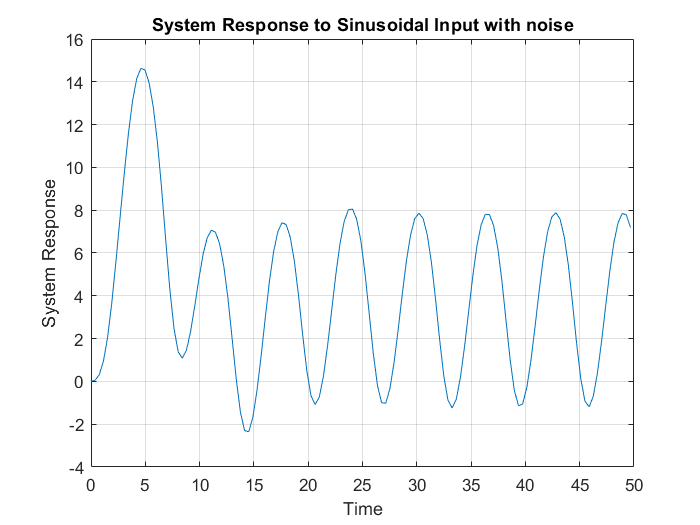


figure()
[y,t_out] = lsim(G_z,u,t);
% Plot the system response
figure;
plot(t_out, y);
xlabel('Time');
ylabel('System Response');
title('System Response to Sinusoidal Input with noise');
grid on;


y_noisy = y+randn(131,1);
[parameter,regres_matrix] = least_square(y_noisy,u,t);

Regression Matrix:
  Columns 1 through 7

         0         0         0         0    1.0000         0         0
    0.5785         0         0         0   20.1761    1.0000         0
   -0.9342    0.5785         0         0   -0.0548   20.1761    1.0000
   -1.7117   -0.9342    0.5785         0   18.7156   -0.0548   20.1761
   -1.2701   -1.7117   -0.9342    0.5785   -6.1622   18.7156   -0.0548
   -3.6908   -1.2701   -1.7117   -0.9342   10.4311   -6.1622   18.7156
   -4.7201   -3.6908   -1.2701   -1.7117   -3.6201   10.4311   -6.1622
   -5.8003   -4.7201   -3.6908   -1.2701    6.7416   -3.6201   10.4311
   -8.5339   -5.8003   -4.7201   -3.6908   10.9095    6.7416   -3.6201
   -9.8890   -8.5339   -5.8003   -4.7201  -17.7016   10.9095    6.7416
  -11.1473   -9.8890   -8.5339   -5.8003   10.6969  -17.7016   10.9095
  -13.4547  -11.1473   -9.8890   -8.5339   -9.2095   10.6969  -17.7016
  -14.1772  -13.4547  -11.1473   -9.8890    5.7336   -9.2095   10.6969
  -14.2611  -14.1772  -13.4547  -11

regres_matrix*parameter

ans =     0.0197
   -0.2406
    0.9843
    2.6949
    2.5346
    5.4331
    5.7676
    7.5149
    9.2878
   10.6318


0.5*sum((y_noisy-y_estimated).^2)

ans = 81.7473

disp(parameter)

   -1.1026
   -0.1129
    0.0092
    0.2780
    0.0197
    0.0003
    0.0142
    0.0423
    0.0510



# he

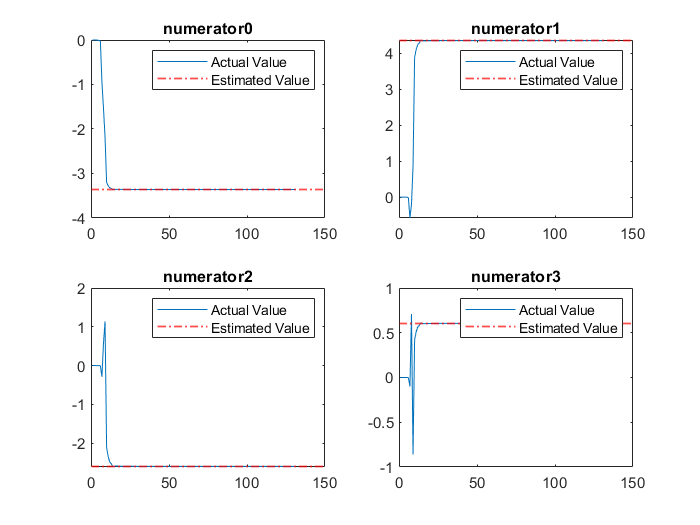

% Create a time vector for simulation
t = 0:T_s:50; % Adjust the time vector as needed

% Initialize the input signal
u = ones(size(t));

% Generate the sum of sinusoidal inputs
for i = 1:num_components
    u = u + G_i(i) * sin(omega_i(i) * t);
end
[y,~] = lsim(G_z,u,t);
[~,parameters] = r_least_square(y,u,t);
[numerator , denominator] = tfdata(G_z, 'v');
actual_params = [denominator(2:end),numerator];

figure()
for i=1:4
    hold on
    subplot(2,2,i)
    plot(parameters(i,:))
    yline(actual_params(i),'-.','Color','r','LineWidth',1)
    legend("Actual Value","Estimated Value")
    title(['numerator',num2str(i-1)])
    hold off
end

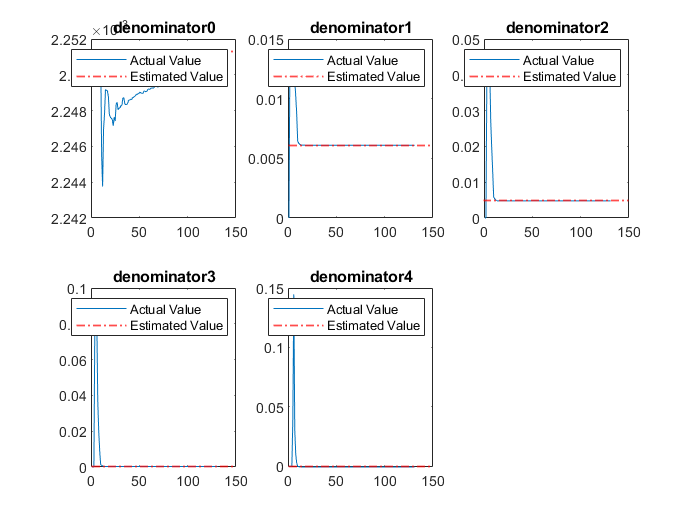

figure()
for i=1:5
    hold on
    subplot(2,3,i)
    plot(parameters(i+4,:))
    yline(actual_params(i+4),'-.','Color','r','LineWidth',1)
    legend("Actual Value","Estimated Value")
    title(['denominator',num2str(i-1)])
    hold off
end

# khe

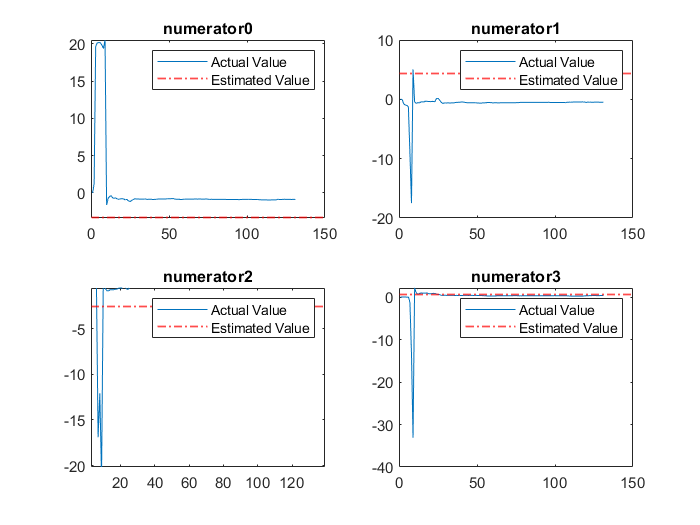

% Create a time vector for simulation
t = 0:T_s:50; % Adjust the time vector as needed

% Initialize the input signal
u = ones(size(t));

% Generate the sum of sinusoidal inputs
for i = 1:num_components
    u = u + G_i(i) * sin(omega_i(i) * t);
end
[y,~] = lsim(G_z,u,t);
y_noisy = y+randn(131,1);
[~,parameters] = r_least_square(y_noisy,u,t);
[numerator , denominator] = tfdata(G_z, 'v');
actual_params = [denominator(2:end),numerator];

figure()
for i=1:4
    hold on
    subplot(2,2,i)
    plot(parameters(i,:))
    yline(actual_params(i),'-.','Color','r','LineWidth',1)
    legend("Actual Value","Estimated Value")
    title(['numerator',num2str(i-1)])
    hold off
end

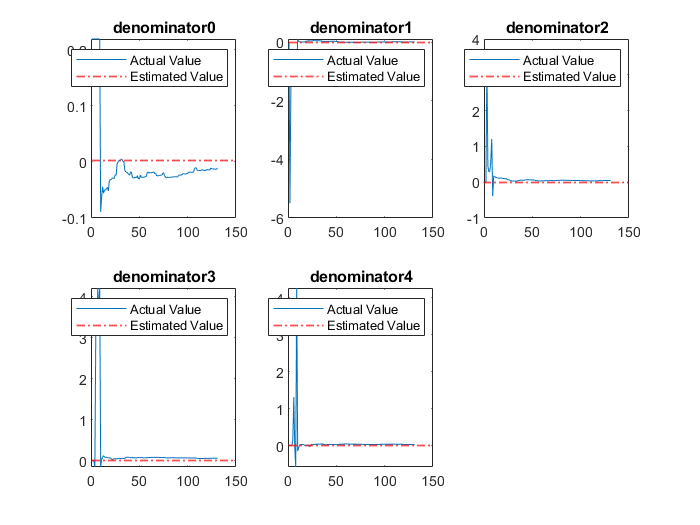

figure()
for i=1:5
    hold on
    subplot(2,3,i)
    plot(parameters(i+4,:))
    yline(actual_params(i+4),'-.','Color','r','LineWidth',1)
    legend("Actual Value","Estimated Value")
    title(['denominator',num2str(i-1)])
    hold off
end